**Ecuaciones No Lineales**

f = @(x) (exp(x) - x.^3)./sqrt(x)

f = function_handle with value:
    @(x)(exp(x)-x.^3)./sqrt(x)


**Método Gráfico**

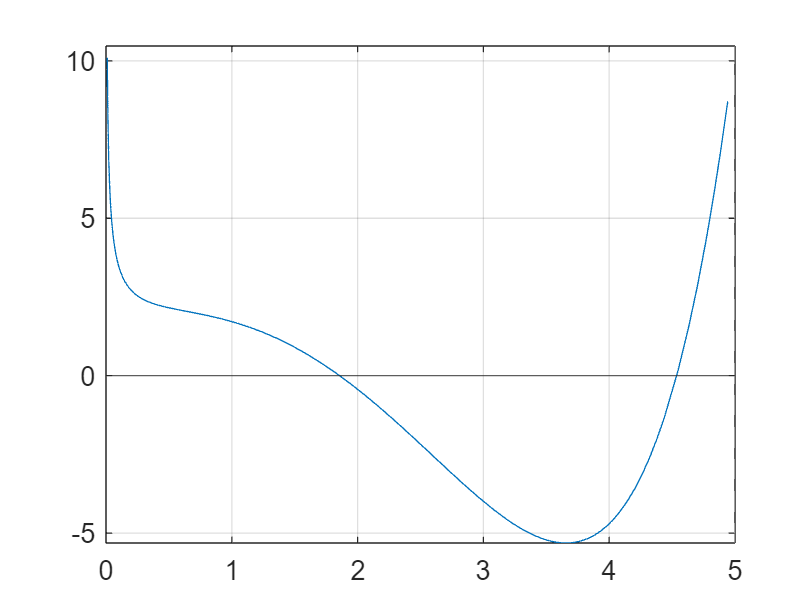

fplot(f,[0.01 5]); grid on;
yline(0)

**Matlab:**

fzero(f,1)

ans = 1.8572

**Método de Bisección:**

% biseccion(f,a,b,itermax)

f = @(x) (exp(x) - x.^3)./sqrt(x);
a = 1;
b = 2;
itermax = 6; % Criterio del error absoluto b-a/2^i+1<Tol, Tol = 0.01

% i = 0;
% ea = NaN
% c = (a+b)/2
% z = [i a c b f(a) f(c) f(b) ea]
% for i = 1:itermax
%     if f(c)*f(a)>0
%         a = c;
%     else
%         b = c;
%     end
%     c = (a+b)/2;
%     ea = ((b-a)/2);
%     z = [z; i a c b f(a) f(c) f(b) ea];
% end
% disp(z)
z = biseccion(f,a,b,itermax)

z =          0    1.0000    1.5000    2.0000    1.7183    0.9036   -0.4320       NaN
    1.0000    1.5000    1.7500    2.0000    0.9036    0.2988   -0.4320    0.2500
    2.0000    1.7500    1.8750    2.0000    0.2988   -0.0518   -0.4320    0.1250
    3.0000    1.7500    1.8125    1.8750    0.2988    0.1273   -0.0518    0.0625
    4.0000    1.8125    1.8438    1.8750    0.1273    0.0387   -0.0518    0.0312
    5.0000    1.8438    1.8594    1.8750    0.0387   -0.0063   -0.0518    0.0156
    6.0000    1.8438    1.8516    1.8594    0.0387    0.0162   -0.0063    0.0078


**Método de Newton-Raphson**

% newton(f,x0,Tol)

f = @(x) (exp(x) - x.^3)./sqrt(x);
x0 = 1;
Tol = 0.01;

% syms x
% df = diff(f,x);
% df = matlabFunction(df);
% dr = 1
% i = 0;
% z = [i x0 dr];
% while(dr>Tol)
%     x1 = x0 - f(x0)/df(x0);
%     dr = abs(x1 - x0)/abs(x1);
%     x0 = x1;
%     i = i + 1;
%     z = [z; i x1 dr];
% end
% disp(z)
z = newton(f,x0,Tol)

z =          0    1.0000    1.0000
    1.0000    2.5061    0.6010
    2.0000    1.9148    0.3088
    3.0000    1.8582    0.0304
    4.0000    1.8572    0.0006


FUNCIONES

function [z] = biseccion(f,a,b,itermax)
    i = 0;
    ea = NaN;
    c = (a+b)/2;
    z = [i a c b f(a) f(c) f(b) ea];
    for i = 1:itermax
        if f(c)*f(a)>0
            a = c;
        else
            b = c;
        end
        c = (a+b)/2;
        ea = ((b-a)/2);
        z = [z; i a c b f(a) f(c) f(b) ea];
    end
end

function z = newton(f,x0,Tol)
    syms x
    df = diff(f,x);
    df = matlabFunction(df);
    dr = 1;
    i = 0;
    z = [i x0 dr];
    while(dr>Tol)
        x1 = x0 - f(x0)/df(x0);
        dr = abs(x1 - x0)/abs(x1);
        x0 = x1;
        i = i + 1;
        z = [z; i x1 dr];
    end
end

function z = puntofijo(g,x0,Tol)
    dr = 1;
    i = 0;
    z = [i x0 dr];
    while(dr>Tol)
        x1 = g(x0);
        dr = abs(x1 - x0)/abs(x1);
        x0 = x1;
        i = i + 1;
        z = [z; i x1 dr];
    end
end